# LEARNING MOTION PATTERNS IN AIS DATA AND DETECTING ANOMALOUS BEHAVIOR

info=parquetinfo('Dati Danimarca pre-processati da AIA\denmark_2023-06-05_downsampled.parquet')

info =   ParquetInfo with properties:

               Filename: "C:\Users\Utente CAL\Documents\GitHub\Vessels-anomaly-detection-with-AIS-data\NOAA_Office for Coastal Management_AIS\Dati Danimarca pre-processati da AIA\denmark_2023-06-05_downsampled.parquet"
               FileSize: 145333199
           NumRowGroups: 2
        RowGroupHeights: [1048576 872617]
          VariableNames: ["t"    "journey"    "vid"    "transtype"    "navstatus"    "shiptype"    "cargotype"    "datasource"    "lat"    "lon"    "t_1"    "t_2"    "latr"    "lonr"    "havr_dist"    "speed_calc"    "report_rate"    …    ] (1×24 string)
          VariableTypes: ["datetime"    "double"    "double"    "string"    "string"    "string"    "string"    "string"    "double"    "double"    "int64"    "int64"    "double"    "double"    "double"    "double"    "double"    …    ] (1×24 string)
    VariableCompression: ["snappy"    "snappy"

rf = rowfilter(["vid"]);% seleziono solo una nave dal dataset già interpolato
rf2 = (rf.vid == 205096000);
dataset = parquetread('Dati Danimarca pre-processati da AIA\denmark_2023-06-05_downsampled.parquet',RowFilter=rf2)

dataset = 235×24 table
             t              journey       vid       transtype           navstatus            shiptype     cargotype    datasource     lat       lon       t_1       t_2       latr        lonr      havr_dist    speed_calc    report_rate    heading_custom        rot         rot_avg       rot_diff      speed_avg    speed_diff    x__index_level_0__
    ____________________    _______    _________    _________    ________________________    _________    _______

ismissing(dataset);
dataset.cargotype=[];
dataset=rmmissing(dataset);

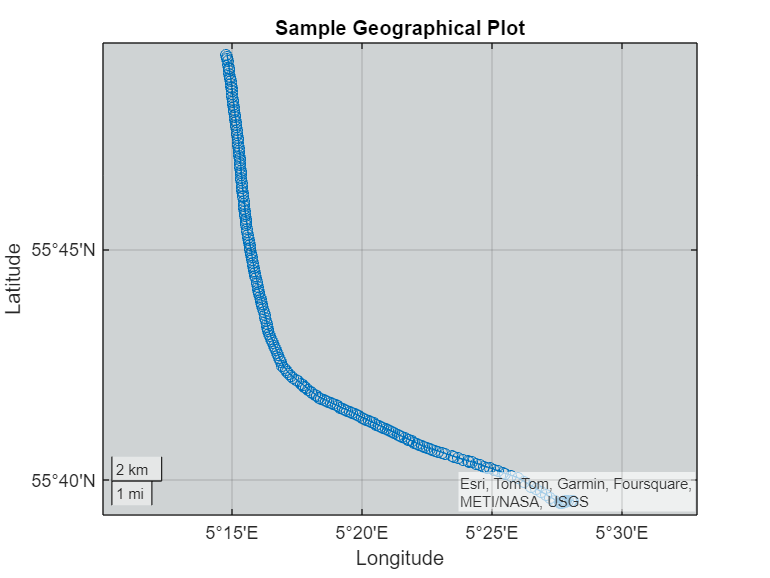


figure
% Create a geographical plot
geoplot(dataset.lat, dataset.lon, 'o-')
title('Sample Geographical Plot')


% Utilizzare la funzione utmzone per ottenere la zona UTM
zone = utmzone(dataset.lat, dataset.lon);
% Ottenere la mappa della proiezione UTM per la zona calcolata
utmstruct = defaultm('utm');
utmstruct.zone = zone;
utmstruct.geoid = wgs84Ellipsoid;
utmstruct = defaultm(utmstruct);
% Convertire tutte le coordinate lat/lon in UTM
[utmX, utmY] = projfwd(utmstruct, dataset.lat, dataset.lon);
% Convertire le coordinate UTM nuovamente in lat/lon
[lat, lon] = projinv(utmstruct, utmX, utmY);

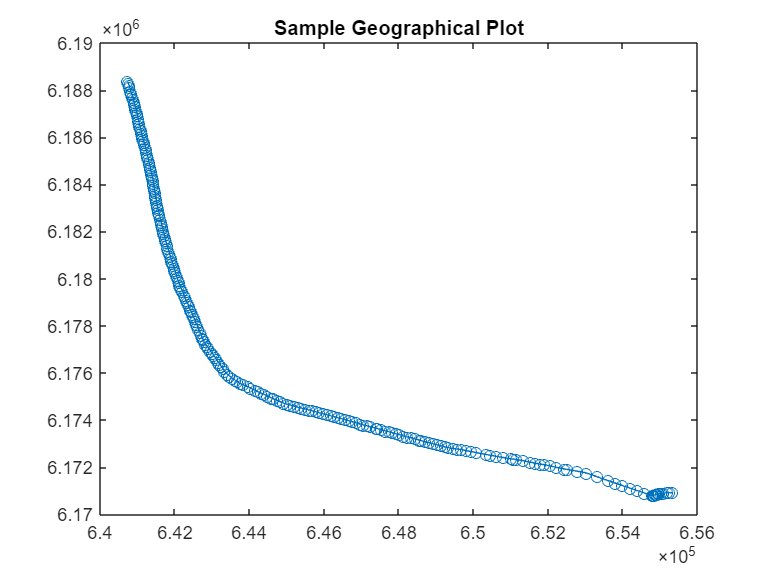

% % dataSubset=dataSubset(1:300,:);
% [x,y,utmzone]=deg2utm(dataset.lat, dataset.lon);
figure
% Create a geographical plot
plot(utmX, utmY, 'o-')
title('Sample Geographical Plot')

figure
% Create a geographical plot
geoplot(lat, lon, 'o-')
title('Sample Geographical Plot')

% Assuming temp is a table and BaseDateTime is a column in the 'dd/mm/yyyy HH:MM' format
dataset.BaseDateTime = datetime(dataset.t,'InputFormat','dd/MM/yyyy HH:mm');

% Convert datetime to seconds since epoch (Unix timestamp)
d = posixtime(dataset.BaseDateTime);

% Calculate time elapsed since the first timestamp
Tsec = d - d(1);
% Assuming 'Tsec' is your array of timestamps in seconds
diff_Tsec = diff(Tsec);

% Find the most common difference, which will be your sample time Ts
Ts = mode(diff_Tsec);

initialCovariance = diag([5,5,0.001,0.001,0,0]);
processNoise = diag([5 5, 0.001,0.001,0,0]);
measureNoise = diag([1e2;1e2;0;0]); % Measurement noise matrix. Units are m^2 and rad^2.

state_vector=[utmX,utmY,dataset.speed_calc, dataset.heading_custom];
state_vector=state_vector';
state_vector=state_vector(:,2:end);
N=length(state_vector);
state_vector=[state_vector;zeros(2,N)];
trueInitialState = state_vector(:,1); 

for i = 2:N
    if i ~= 1
        trueStates(:,i) = stateModel(state_vector(:,i-1),Ts) +sqrt(processNoise)*randn(6,1);  
    end
    measurements(:,i) = measureModel(state_vector(:,i)) + sqrt(measureNoise)*randn(4,1);
end

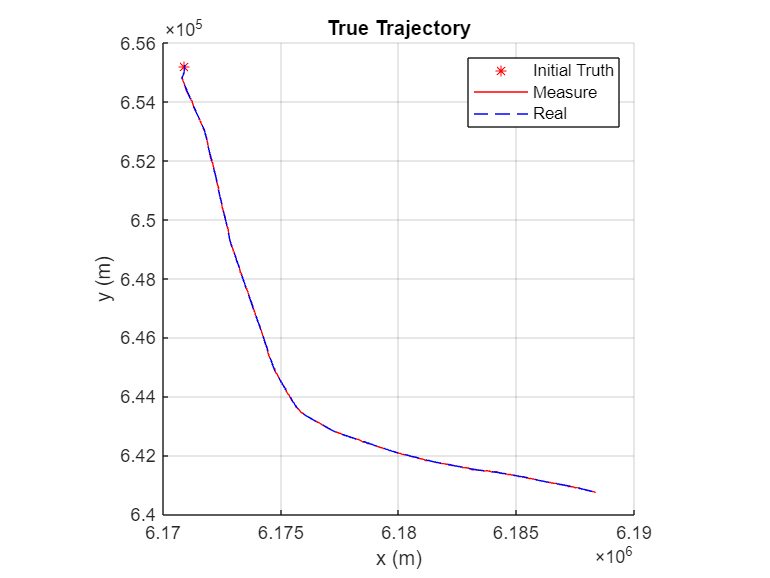

figure
hold on
plot(measurements(2,2),measurements(1,2),"r*",DisplayName="Initial Truth")
plot(measurements(2,2:end),measurements(1,2:end),"r",DisplayName="Measure")
plot(state_vector(2,:),state_vector(1,:),"b--",DisplayName="Real")

grid on
xlabel("x (m)")
ylabel("y (m)")
title("True Trajectory")
legend(Location="northeast")

axis square


obj = extendedKalmanFilter('HasAdditiveMeasurementNoise',true);
obj.StateTransitionFcn = @(x,u)stateModel(x,Ts);
obj.MeasurementFcn =  @(x,u)measureModel(x);
obj.StateTransitionJacobianFcn =@(x,u)stateTransitionJacobianFcn(x,Ts);

obj.StateCovariance=initialCovariance;
obj.ProcessNoise=processNoise;
obj.MeasurementNoise=measureNoise;
obj.State = trueInitialState;


for i=2:N
    correct(obj,measurements(:,i),[]);
    predict(obj,measurements(:,i));
    estimateStates(:,i)=obj.State;
end

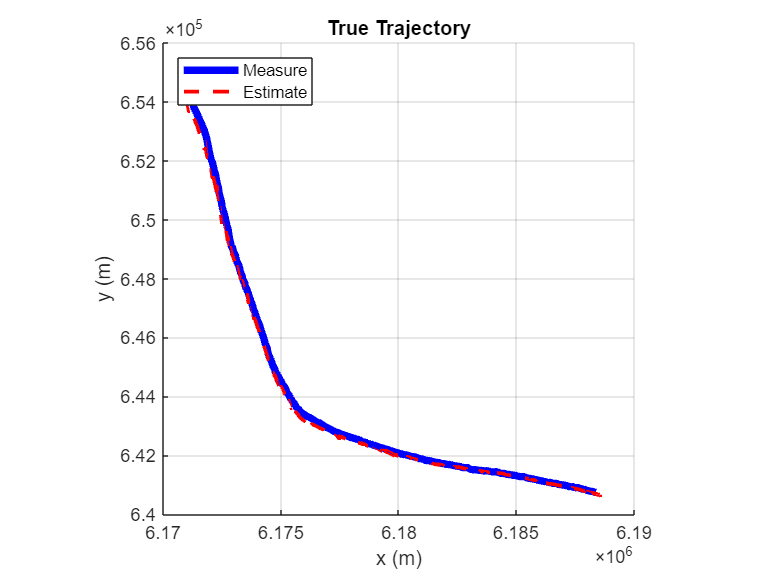

figure
hold on
plot(measurements(2,2:end),measurements(1,2:end),"b",'LineWidth',4,DisplayName="Measure")

plot(estimateStates(2,2:end),estimateStates(1,2:end),"r--",'LineWidth',2,DisplayName="Estimate")
legend(Location="northwest")
grid on
xlabel("x (m)")
ylabel("y (m)")
title("True Trajectory")
axis square

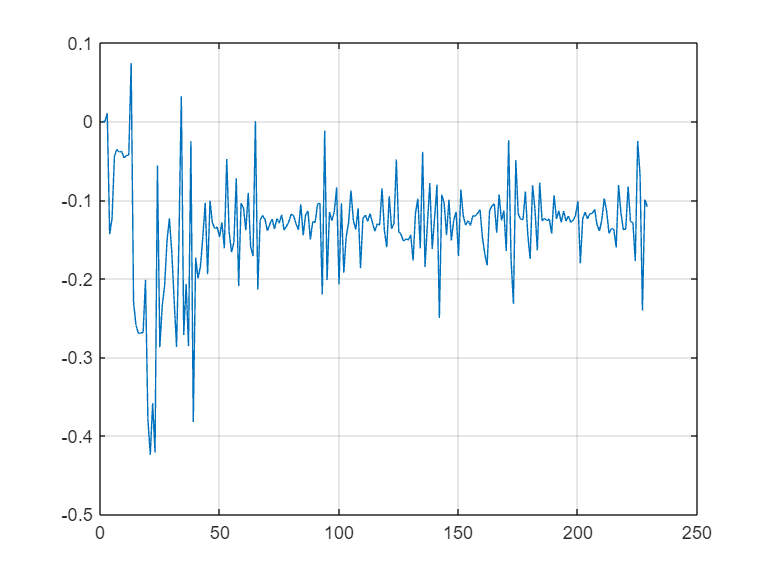

figure
grid on
plot(estimateStates(5,:))
grid on

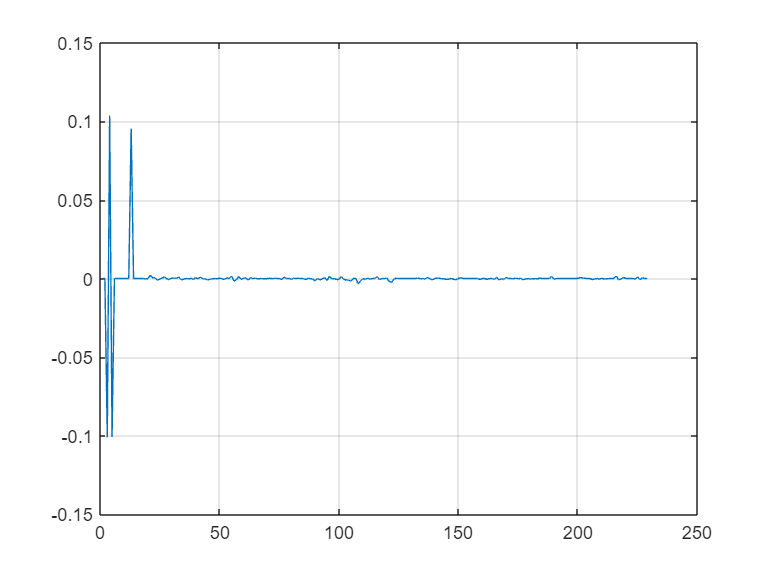

figure
plot(estimateStates(6,:))
grid on

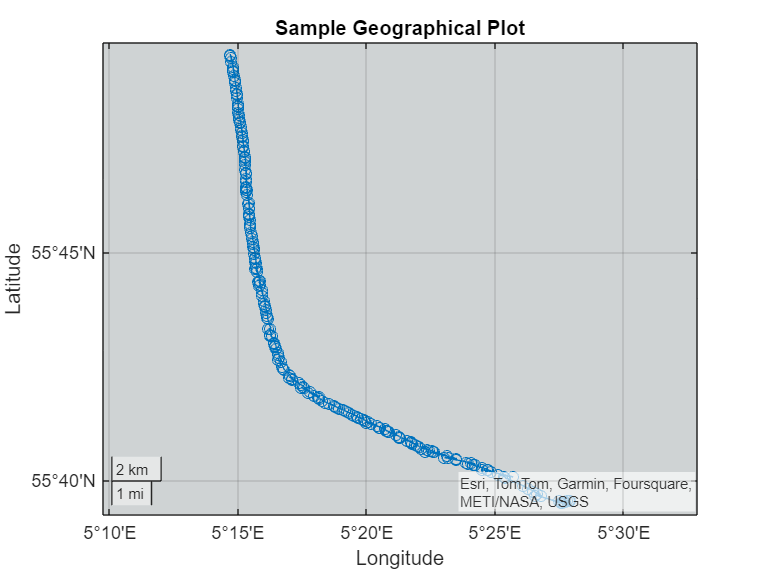

% Convertire le coordinate UTM nuovamente in lat/lon

[lat_e, lon_e] = projinv(utmstruct, estimateStates(1,2:end), estimateStates(2,2:end));
figure
% Create a geographical plot
geoplot(lat_e, lon_e, 'o-')
title('Sample Geographical Plot')